% clear all;
% clc;

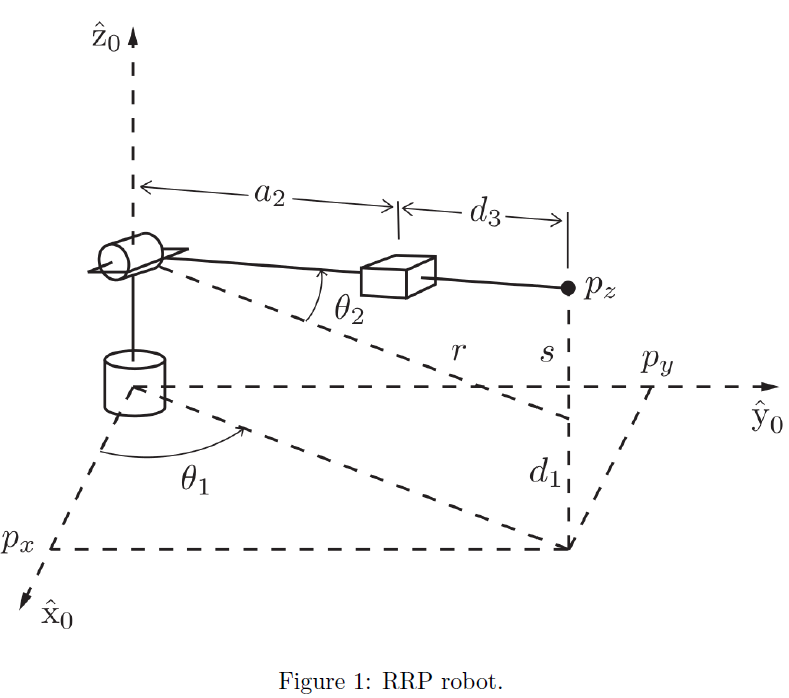

## 1) Forward Kinematics:


$$T_{H\;} =R_z \left(\theta_1 \right)\;\cdot T_z \left(d_1 \right)\cdot R_y \left(\theta_2 \right)\cdot T_x \left(a_2 \right)\cdot T_x \left(d_3 \right)$$



% defining Robot's Links (Assumption) in cm
d1 = 10 ; 
a2 = 15 ; 
Links = [d1 a2];
theta1 = deg2rad(45);
theta2 = deg2rad(-45);
d3 = 20;
% Testing the FK 
var = [theta1 theta2 d3]

var =     0.7854   -0.7854   20.0000


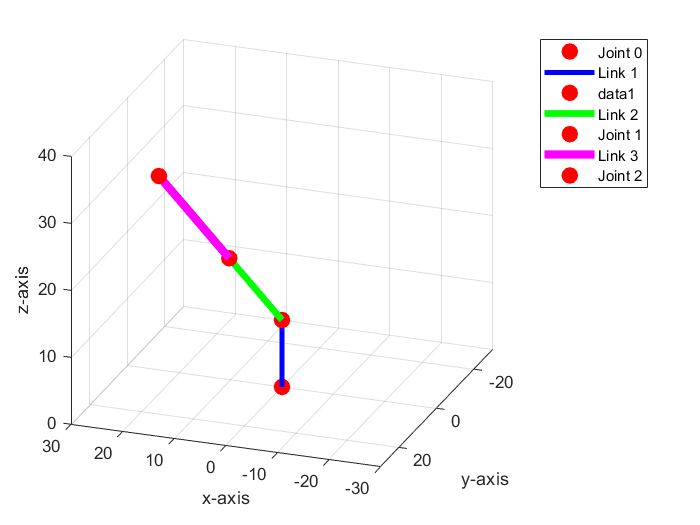

robot(Links,var)


% syms theta1 theta2 d3 d1 a2

T_H = RotR("z",theta1) * Trans("z",d1) * RotR("y",theta2) * Trans("x",a2) * Trans("x",d3)

T_H =     0.5000   -0.7071   -0.5000   17.5000
    0.5000    0.7071   -0.5000   17.5000
    0.7071         0    0.7071   34.7487
         0         0         0    1.0000


% T_H = simplify(T_H)


## 2) Inverse Kinematics:

pai = pi;         % = pi If working with radians , = 180 if working with degrees
% syms x y z        % Point (x,y,z) is input to the IK. x,y,z are known values
x = T_H(1,4);
y = T_H(2,4);
z = T_H(3,4);
disp("First Applicable Solution")

First Applicable Solution


theta11 = atan2(y,x)

theta11 = 0.7854

s = z - d1;
r = sqrt(x^2 + y^2);
theta21 = -atan2(s,r)

theta21 = -0.7854

d31 = sqrt(r^2 + s^2) - a2

d31 = 20

robot([d1 a2],[theta11 theta21 d31])



disp("Second Applicable Solution")

Second Applicable Solution


theta12 = atan2(y,x) + pai 

theta12 = 3.9270

theta22 = pai - -atan2(s,r)  

theta22 = 3.9270

d32 = sqrt(r^2 + s^2) - a2

d32 = 20

robot([d1 a2],[theta12 theta22 d32])

## 3) Jacobian:

% FK
syms d1 a2 d3 theta1 theta2 
T_H = RotR("z",theta1) * Trans("z",d1) * RotR("y",theta2) * Trans("x",a2) * Trans("x",d3);

%% Classical Approach
r = (a2 + d3)*cos(theta2);
s = (a2 + d3)*sin(theta2);

x = r*cos(theta1)

$$x = \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right)$$

y = r*sin(theta1)

$$y = \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right)$$

z = d1 - s

$$z = d_{1}-\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right)$$


J_classical = jacobian([x;y;z] , [theta1 theta2 d3]);
J_classical = simplify(J_classical)

$$J\_classical = \left(\begin{array}{ccc} -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{2}\right) \end{array}\right)$$


%% Geometrical Approach (Skew Theory)
T00 = eye(4);
T01 = RotR("z",theta1) * Trans("z",d1);
T02 = RotR("z",theta1) * Trans("z",d1) * RotR("y",theta2) * Trans("x",a2);
T03 = T_H;

% defining the translation vector of each joint
On = T_H(1:3,4);    % Tranlation vector of the FK 
O0 = T00(1:3,4);
O1 = T01(1:3,4);
O2 = T02(1:3,4);

% defining the u vector from the R matrix of each joint
u1 = T00(1:3,3);    % rotation around z-axis therefore extract the 3rd column
u2 = T01(1:3,2);    % rotation around y-axis therefore extract the 2nd column
u3 = T03(1:3,1);    % translation along x-axis therefore extract the 1st column


J1(1:3,1) = cross(u1,(On - O0));
J1(4:6,1) = u1;
% J1 = simplify(J1)

J2(1:3,1) = cross(u2,(On - O1));
J2(4:6,1) = u2;
% J2 = simplify(J2)

J3(1:3,1) = u3;
J3(4:6,1) = 0;
% J3 = simplify(J3)

J_skew = simplify([J1 J2 J3])

$$J\_skew = \left(\begin{array}{ccc} -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{2}\right)\\ 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & \cos\left(\theta_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$



%% Numerical Approach
R = T_H(1:3,1:3);

% parameter theta1
Td_theta1 = diff(RotR("z",theta1),theta1) * Trans("z",d1) * RotR("y",theta2) * Trans("x",a2) * Trans("x",d3) ...
            * [inv(R) zeros(3,1); 0 0 0 1];
J_numerical(1:6,1) = [Td_theta1(1,4) ; Td_theta1(2,4) ; Td_theta1(3,4) ; Td_theta1(3,2) ; Td_theta1(1,3) ; Td_theta1(2,1)];

% parameter theta2
Td_theta2 = RotR("z",theta1) * Trans("z",d1) * diff(RotR("y",theta2),theta2) * Trans("x",a2) * Trans("x",d3) ...
            * [inv(R) zeros(3,1); 0 0 0 1];
J_numerical(1:6,2) = [Td_theta2(1,4) ; Td_theta2(2,4) ; Td_theta2(3,4) ; Td_theta2(3,2) ; Td_theta2(1,3) ; Td_theta2(2,1)];

% parameter d3 
Td_d3 = RotR("z",theta1) * Trans("z",d1) * RotR("y",theta2) * Trans("x",a2) * diff(Trans("x",d3),d3) ...
            * [inv(R) zeros(3,1); 0 0 0 1];
J_numerical(1:6,3) = [Td_d3(1,4) ; Td_d3(2,4) ; Td_d3(3,4) ; Td_d3(3,2) ; Td_d3(1,3) ; Td_d3(2,1)];
J_numerical = simplify(J_numerical)

$$J\_numerical = \left(\begin{array}{ccc} -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{2}\right)\\ 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & \cos\left(\theta_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

## 4) Singularity Checks

Jacobians Can be used also for Singularity Cases in the Robot configuration.

Singularity occurs when **one or more row/column are zeros** in the Jacobian Matrix. In ***Zero column*** case, it means that a particular output parameter (x,y,z,$\varphi_x \;$, $\varphi_y$, $\varphi_z$) became incontrollable by neither one of the joints. While ***Zero row ***means that a particular joint does not have an effect on a certain output parameter.

determinant = simplify(det(J_classical))

$$determinant = -\cos\left(\theta_{2}\right)\,{\left(a_{2}+d_{3}\right)}^{2}$$

Singul_theta1 = solve(determinant,theta1)

 
Singul_theta1 =
 
Empty sym: 0-by-1
 


Singul_theta2 = solve(determinant,theta2)

$$Singul\_theta2 = \frac{\pi }{2}$$

Singul_d3 = solve(determinant,d3)

$$Singul\_d3 = \left(\begin{array}{c} -a_{2}\\ -a_{2} \end{array}\right)$$

This configuration has 4 singularity cases. [$\theta_2 ,d_3$] = $\left\lbrack \frac{\pi }{2},-a_2 \right\rbrack$ / $\left\lbrack \frac{\pi }{2},a_2 \right\rbrack$  /  $\left\lbrack -\frac{\pi }{2},-a_2 \right\rbrack$  /  $\left\lbrack -\frac{\pi }{2},a_2 \right\rbrack$

a2 = 15;
disp('Singularity case 1')

Singularity case 1


theta2 = Singul_theta2

$$theta2 = \frac{\pi }{2}$$

d3 = -subs(Singul_d3(1),a2)

$$d3 = 15$$

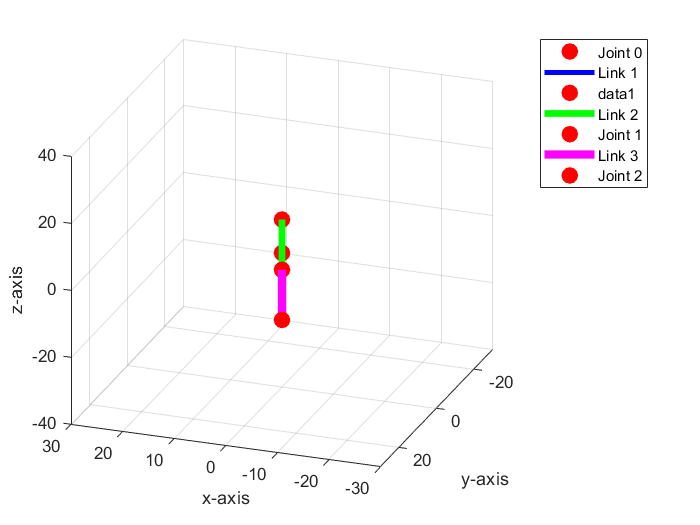

robot([10 a2],[0 Singul_theta2 -subs(Singul_d3(1),a2)])

disp('Singularity case 2')

Singularity case 2


theta2 = Singul_theta2

$$theta2 = \frac{\pi }{2}$$

d3 = subs(Singul_d3(1),a2)

$$d3 = -15$$

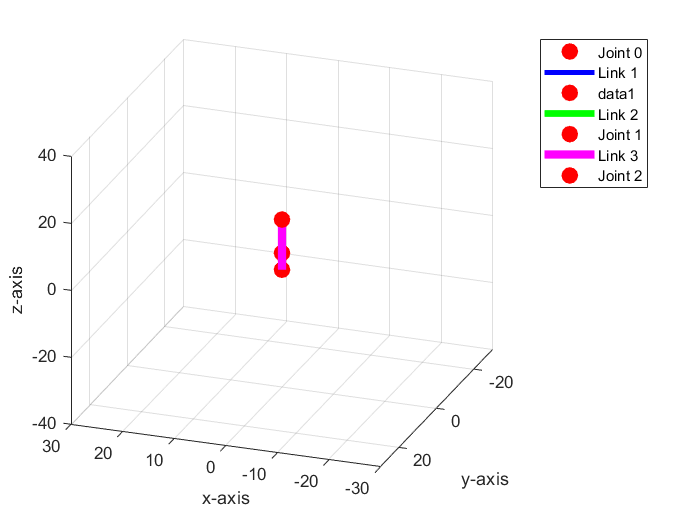

robot([10 a2],[45 Singul_theta2 subs(Singul_d3(1),a2)])

disp('Singularity case 3')

Singularity case 3


theta2 = -Singul_theta2

$$theta2 = -\frac{\pi }{2}$$

d3 = -subs(Singul_d3(1),a2)

$$d3 = 15$$

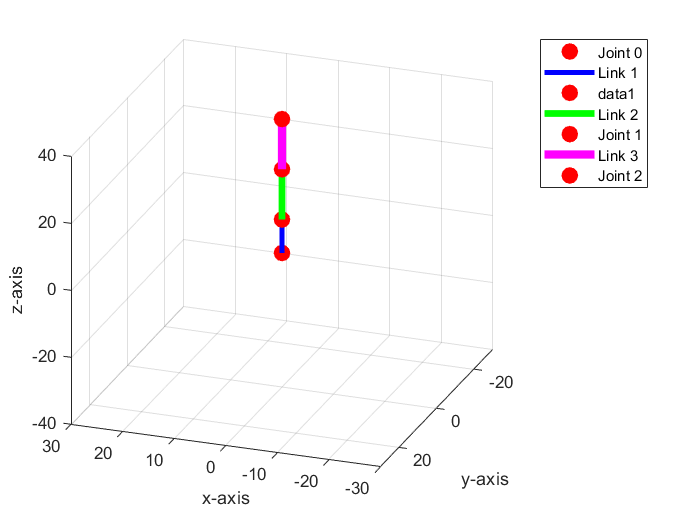

robot([10 a2],[90 -Singul_theta2 -subs(Singul_d3(1),a2)])

disp('Singularity case 4')

Singularity case 4


theta2 = -Singul_theta2

$$theta2 = -\frac{\pi }{2}$$

d3 = subs(Singul_d3(1),a2)

$$d3 = -15$$

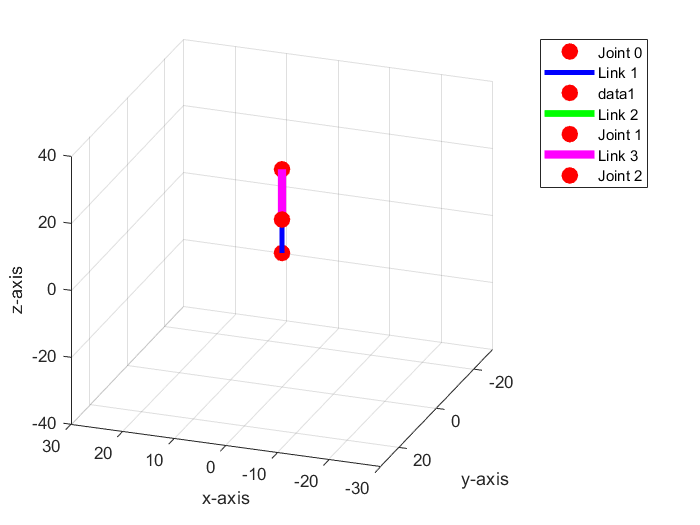

robot([10 a2],[45 -Singul_theta2 subs(Singul_d3(1),a2)])

## 5) Velocity of the Tool Frame:

The computed Jacobian matrix can be futher used to map from the joints' velocity space to Tool's velocity space.


$$\left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Y} \\
\dot{Z} 
\end{array}\right\rbrack =J\left(\theta_1 \left(t\right),\theta_2 \left(t\right),d_3 \left(t\right)\right)\cdot \left\lbrack \begin{array}{c}
\dot{\theta_1 } \\
\dot{\theta_2 } \\
\dot{d_3 } 
\end{array}\right\rbrack$$


        
$$q\left(t\right)=\;\left\lbrack \theta_1 \;\;\theta_2 \;\;d_3 \right\rbrack$$


        
$$\dot{q} \left(t\right)=\left\lbrack \dot{\theta_1 } \;\;\dot{\theta_2 } \;\;\dot{d_3 } \right\rbrack$$


syms t theta1 theta2 d3 a2
q_t = [sin(t) cos(2*t) sin(3*t)];                      % Joints in function of t
q_dt = diff(q_t,t);                                     % derivative of q_t
J_t = subs(J_classical, [theta1 theta2 d3 a2], [q_t 15]);    % Jacobian(theta1(t),theta2(2),d3(t))
% J_t = simplify(J_t)
V_t = J_t * q_dt';
ts = 1:100 ;
q_t = subs(q_t',t,ts);
q_dt= subs(q_dt',t,ts);
V_t = subs(V_t,t,ts);


Figure1:

These graphs show graphically how the joints' angles (in radians) changes in time with their given input functions

        
$$\mathrm{Joint}\;1-\theta_1 =\mathrm{sin}\left(t\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{Joint}\;2-\theta_2 =\mathrm{cos}\left(2t\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{Joint}\;3-d_3 =\mathrm{sin}\left(3t\right)$$


% --------------------------------------
disp("Position Plotting of the Joints")

Position Plotting of the Joints


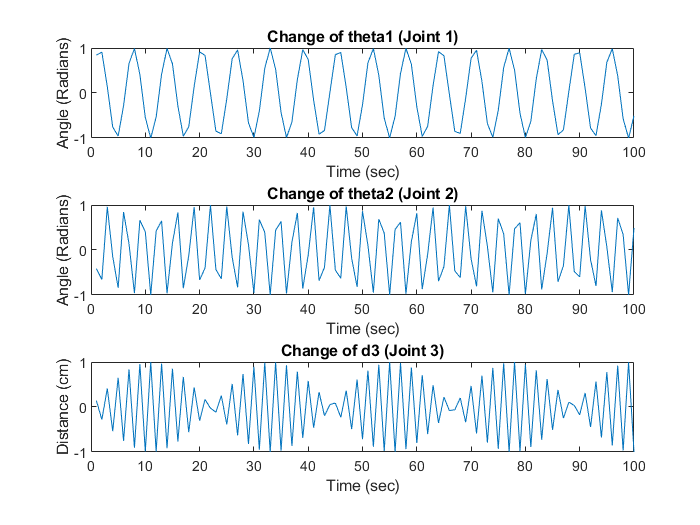

figure
subplot(3,1,1)
plot(ts,q_t(1,:))
title(" Change of theta1 (Joint 1) ")
xlabel("Time (sec)")
ylabel("Angle (Radians)")

subplot(3,1,2)
plot(ts,q_t(2,:))
title(" Change of theta2 (Joint 2) ")
xlabel("Time (sec)")
ylabel("Angle (Radians)")

subplot(3,1,3)
plot(ts,q_t(3,:))
title(" Change of d3 (Joint 3) ")
xlabel("Time (sec)")
ylabel("Distance (cm)")

Figure 2 

    The rate of change of the angles of the joints

            
$$\textrm{Joint}\;1-\theta_1 =\mathrm{cos}\left(t\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Joint}\;2-\theta_2 =-2\mathrm{sin}\left(2t\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Joint}\;3-d_3 =3\mathrm{cos}\left(3t\right)$$


% --------------------------------------
disp("Velocity Plotting of the Joints")

Velocity Plotting of the Joints


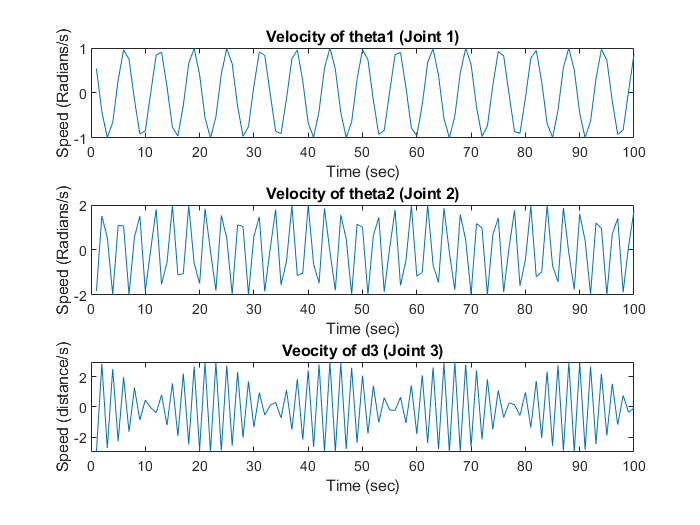

figure
subplot(3,1,1)
plot(ts,q_dt(1,:))
title(" Velocity of theta1 (Joint 1) ")
xlabel("Time (sec)")
ylabel("Speed (Radians/s)")

subplot(3,1,2)
plot(ts,q_dt(2,:))
title(" Velocity of theta2 (Joint 2) ")
xlabel("Time (sec)")
ylabel("Speed (Radians/s)")

subplot(3,1,3)
plot(ts,q_dt(3,:))
title(" Veocity of d3 (Joint 3) ")
xlabel("Time (sec)")
ylabel("Speed (distance/s)")

Figure 3 

        Describes the Tool Frame velocity in each component of the cartesian workspace X , Y , Z

% --------------------------------------
disp("Velocity Plotting of the Tool Frame")

Velocity Plotting of the Tool Frame


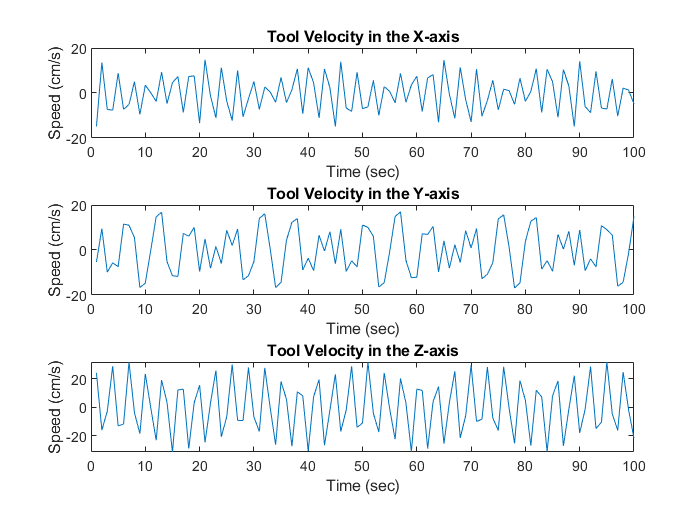

figure
subplot(3,1,1)
plot(ts,V_t(1,:))
title("Tool Velocity in the X-axis")
xlabel("Time (sec)")
ylabel("Speed (cm/s)")

subplot(3,1,2)
plot(ts,V_t(2,:))
title("Tool Velocity in the Y-axis")
xlabel("Time (sec)")
ylabel("Speed (cm/s)")

subplot(3,1,3)
plot(ts,V_t(3,:))
title("Tool Velocity in the Z-axis")
xlabel("Time (sec)")
ylabel("Speed (cm/s)")